# Calcualtion of Inter Hamming Distance for Polarization Measurements

For thepolarization sensitivity tests, for each device we calculate the Hamming Distance to its TE and to its TM states at every polarization state.

## Read azimuthal and elliptcial results for a device design

First extract the data from the H5 files. 

clear all;
folder = 'G:\My Drive\PRL Group\04 Projects\2 Juan\1 OPUF ANT2 CHIP02\with AuNP\polarization Test\';

%% Design 1
%files{1} = 'dev14_20210525_PS_Azimuth.smp';
%files{2} = 'dev14_20210525_PS_Elliptical.smp';

%% Design 2
%files{1} = 'dev20_20210525_PS_Azimuth.smp';
%files{2} = 'dev20_20210525_PS_Elliptical.smp';

%% Design 3
files{1} = 'dev24_20210525_PS_Azimuth.smp';
files{2} = 'dev24_20210525_PS_Elliptical.smp';

%Data is tagged using var to store the three components of the 
%stoke parameters S1, S2 and S3, no value for S0 is stored, but 
% in general allmeasurements are carried using the same input power
% and have a similar average output power.
file_ind = 1;
for file = files
    filename = strcat(folder,file{1});
    struct = h52struct(filename);
    meas = struct.project.measurements; 
    device=[];
    clear ('angle','s');
    idx = 1;
    for i = 1:length(meas)
        
        s = meas(i).var;
        if (sum(s)==0)
            continue;
        end
        
        [xsi,phi,~]=cart2sph(s(1),s(2),s(3)); 
        xsi = xsi/2;
        phi = phi/2;
        
        %xsi = asin(s(3))/2;
        %phi = acos(s(1)/cos(2*xsi))/2;  
        %disp(sprintf('%s \t %2.3f %2.3f',num2str(s,'%2.3f'), xsi*180/pi, phi*180/pi));
        angle(idx,:) = [xsi phi];
        m = meas(i).spectra;
        device(:,idx) = m(:,2)-max(m(:,2)); %Normalized if in dBm
        lambda = m(:,1);
        idx = idx+1;
    end
    dataset{file_ind} = device;
    angles{file_ind} = angle';
    file_ind = file_ind+1;
end

dataset2 = [dataset{:}];
angles2 = [angles{:}]';

We now compute  two sets of Hamming Distances, one comparing all responses to the TE response and one comparing all responses to the TM response. 


clear('resTE','resTEs','resTM','resTMs');
for idx_dev = 1:size(dataset2,2)
        idx_TM = findAngle(angles2, [0 0]); 
        idx_TM = idx_TM(1);
        idx_TE = findAngle(angles2, [pi/2 0]); idx_TE = idx_TE(1);
        
        data_refTM = dataset2(:,idx_TM);   data_refTM = data_refTM-max(data_refTM);
        data_refTE = dataset2(:,idx_TE);   data_refTE = data_refTE-max(data_refTE);
        data_dev  =  dataset2(:,idx_dev);
        
        [data_refTMs, data_devstm, lambda_stm] = shiftSpectra(data_refTM,data_dev,lambda);
        [data_refTEs, data_devste, lambda_ste] = shiftSpectra(data_refTE,data_dev,lambda);
        
        L=0.15; mode = 'all'; 
        resTE(idx_dev,:) = LHD_Compute(lambda, [data_refTE, data_dev], mode, L);
        resTEs(idx_dev,:) = LHD_Compute(lambda_stm, [data_refTEs, data_devste], mode, L);

        resTM(idx_dev,:) = LHD_Compute(lambda, [data_refTM, data_dev], mode, L);
        resTMs(idx_dev,:) = LHD_Compute(lambda_ste, [data_refTMs, data_devstm], mode, L);
end

## **Now the plots**

We will use 'x' to mark average raw devices and 'o' to mark the responses shifted in spectrum.  

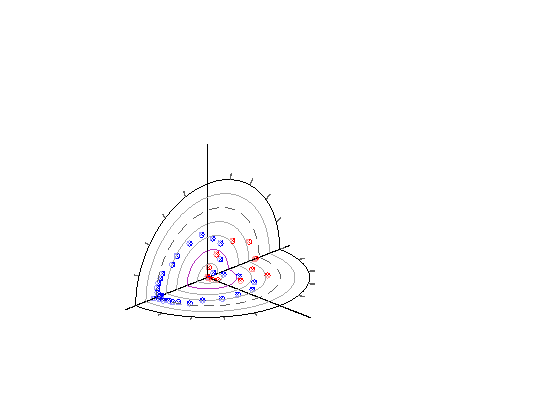

clf, hold off;
h(1) = polarscatter3(angles2(:,1)*2,angles2(:,2)*2,resTM(:,3),...
    'x','Color','r','MarkerSize',4,'DisplayName','HD to TM response');
hold on;
h(2) = polarscatter3(angles2(:,1)*2,angles2(:,2)*2,resTMs(:,3),...
    'o','Color','r','MarkerSize',4,'DisplayName','HD to Shifted TM response');
h(3) =polarscatter3(angles2(:,1)*2,angles2(:,2)*2,resTE(:,3),...
    'x','Color','b','MarkerSize',4,'DisplayName','HD to TE response');
h(4) =polarscatter3(angles2(:,1)*2,angles2(:,2)*2,resTEs(:,3),...
    'o','Color','b','MarkerSize',4,'DisplayName','HD to Shifted TE response');

    %hleg = legend([h],'Location', 'Best');
    %legend boxoff;
    legend off;

exportgraphics(gcf,'test.png','Resolution',1200,'BackgroundColor','#CCCCCC')